clear;


M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];


x_07 = [0.01; 0.01; 0.01; 0.01];
x_0 = x_07;

alpha = 2;

cvx_begin sdp

variable P(4, 4)
variable Y1(1, 4)
variable mumu
minimize mumu
P > 0.0001 * eye(4);

P*A'+A*P + 2*alpha*P + Y1'*B' +B*Y1 <= 0;

[P x_0;
 x_0' 1] > 0;

[P Y1';
    Y1 mumu] > 0;


cvx_end

 
Calling SDPT3 4.0: 67 variables, 20 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 20
 dim. of sdp    var  = 18,   num. of sdp  blk  =  4
 dim. of free   var  = 17 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.0e+01|2.6e+02|2.1e+05| 9.996000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.941|0.942|4.1e+00|1.5e+01|2.5e+03| 9.585632e+00 -9.035051e+00| 0:0:00| chol  1  1 
 2|0.923|0.942|3.2e-01|8.7e-01|4.2e+01| 2.099917e+00 -1.890000e+00| 0:0:00| chol  1  1 
 3|0.967|0.9


K = Y1 *pinv(P)

K =    -0.7765    0.5156   -0.1634   -0.1039





f = 0;
tspan = [0 2000];

% Решение ОДУ
[t, x] = ode45(@(t,x) pendulum_ode(t,x,K,f,m,M,l,g), tspan, x_0);

u = zeros(length(t), 1);
for i = 1:length(t)
    [~, u_i] = pendulum_ode(t(i), x(i, :)', K, f, m, M, l, g);
    u(i) = u_i;
end



disp('phi');

phi


max_phi = max(x(:,3))

max_phi = 31.3704

min(x(:,3))

ans = -1.3946e+04

disp('a');

a


max_a = max(x(:,1))

max_a = 2.8794e+03

min(x(:,1))

ans = -9.9762

disp('u');

u


max_u = max(u)

max_u = 46.2223

min(u)

ans = -43.7284

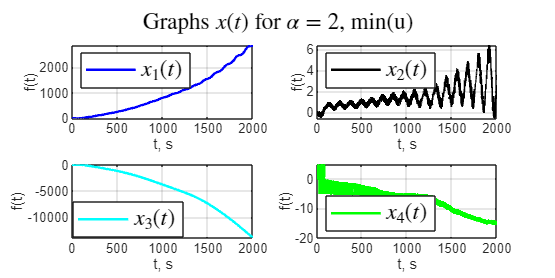



% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x(:,1), 'b-', 'LineWidth',1.5); 
legend('$x_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 80])
%ylim([-0.04 0.08])
grid()

%figure('Position', [100 100 800 400])
subplot(2,2,2);
plot(t, x(:,2), 'k-', 'LineWidth',1.5); 
legend('$x_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 80])
%ylim([-0.32 0.08])
grid()

subplot(2,2,3);
plot(t, x(:,3), 'c-', 'LineWidth',1.5); 
legend('$x_3 (t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'best')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 80])
grid()

subplot(2,2,4);
plot(t, x(:, 4), 'g-', 'LineWidth',1.5);
legend('$x_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southwest')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 80])
%ylim([0 6.5])
grid()


sgtitle('Graphs $x(t)$ for $\alpha = 2$, min(u)','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\' ...
    'pic_fix\4_4_x_2.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

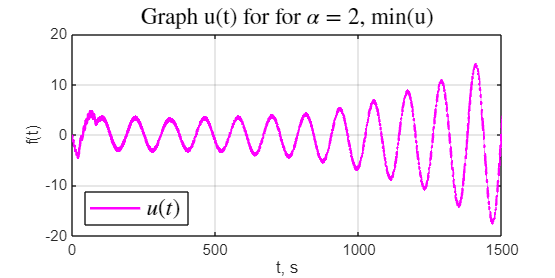





figure('Position', [100 100 800 400])
plot(t, u, 'm-', 'LineWidth',1.5);
legend('$u(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southwest')
ylabel('f(t)')
xlabel('t, s')
title('Graph u(t) for for $\alpha = 2$, min(u)','Interpreter','latex',  'FontSize', 14)
xlim([0 1500])
grid()


full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\TAU_Course_Project\' ...
    'pic_fix\4_4_u_2.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);